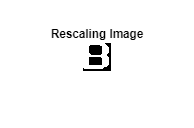

clc; clear; close all; % Clear console, variables, and figures
size = 28; % Define image size
fileID = fopen('input_bram_to_cnn_image.mem', 'rt');
data = textscan(fileID, '%s');
fclose(fileID);
binary_img = strcmp(data{1}, '1'); % Convert '1' to 1 (white), others to 0 (black)
img = reshape(binary_img, size, size)'; % Reshape and transpose to form image matrix
imshow(img, []); title('Rescaling Image'); % Display the image

resized_img = imresize(img, [size, size]); % Resize image (same size in this case)

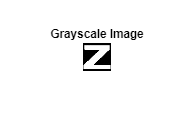

% Step 1: Read the image
img = imread('class_Z_3.jpg');
clear size
% Step 2: Convert to grayscale if it's RGB
if size(img, 3) == 3
    img_gray = rgb2gray(img);
else
    img_gray = img;
end

% Step 3: Convert to double and normalize (optional, range 0 to 1)
img = double(img_gray) / 255;

% Step 4: Display and verify
imshow(img, []);
title('Grayscale Image');

%layer 1 conv

filter_values_1 = squeeze(h5read('my_checkpoint.weights.h5', '/layers/conv2d/vars/0'))'

filter_values_1 = 3×3 single matrix
    0.5516    0.5476   -0.0048
    0.8511    1.1640    0.5468
    0.2417    1.3339    1.1784




bias_1=squeeze(h5read('my_checkpoint.weights.h5', '/layers/conv2d/vars/1'));

img

img =          0         0         0         0    0.0039         0    0.0078         0         0         0         0         0         0         0         0         0         0    0.0039    0.0039         0         0    0.0039         0         0         0    0.0039         0    0.0039
    0.0039         0         0    0.0118         0         0    0.0039         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0039    0.0039         0         0         0         0
         0    0.6118    0.8706    0.8392    0.8667    0.8549    0.8392    0.8863    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8588    0.8588    0.8588    0.8588    0.8588    0.8588    0.8588    0.8627    0.8627    0.8627    0.6078    0.0039
         0    0.7176    0.9882    1.0000    1.0000    1.0000    0.9961    0.9922    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000 

conv_result = conv2_same_size_no_flip(img, filter_values_1)+bias_1;

conv_result

conv_result = 28×28 single matrix
    0.1942    0.1899    0.2029    0.2068    0.1964    0.2012    0.2034    0.1966    0.1890    0.1890    0.1890    0.1890    0.1890    0.1890    0.1890    0.1890    0.1911    0.1957    0.1969    0.1923    0.1911    0.1982    0.2022    0.1952    0.1921    0.1936    0.1945    0.1936
    0.9145    2.0343    2.4936    2.5539    2.5676    2.5321    2.5684    2.5985    2.5708    2.5651    2.5651    2.5651    2.5651    2.5651    2.5651    2.5605    2.5552    2.5564    2.5586    2.5565    2.5543    2.5586    2.5678    2.5720    2.5684    2.2669    1.2151    0.3433
    1.3714    3.5012    4.8521    5.1384    5.1402    5.1301    5.1199    5.1515    5.1716    5.1534    5.1534    5.1534    5.1534    5.1534    5.1534    5.1513    5.1421    5.1335    5.1372    5.1424    5.1434    5.1387    5.1378    5.1390    5.1442    4.6840    2.8373    0.8853
    1.4288    4.0365    5.9847    6.4110    6.4261    6.4432    6.4185    6.4315    6.4546    6.4493    6.4493    6.4493   

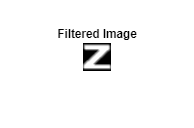

conv_clipped = max(conv_result, 0);
% Display the result
imshow(conv_clipped, []);

title('Filtered Image');

%max pool layer1
size=28;
% Define pooling window size
pool_size = 2;
% Initialize output size
pooled_output_1 = zeros(floor(size/pool_size), floor(size/pool_size));

% Perform 2x2 max pooling
for i = 1:pool_size:size-pool_size+1
    for j = 1:pool_size:size-pool_size+1
        block = conv_clipped(i:i+1, j:j+1);
        pooled_output_1((i+1)/2, (j+1)/2) = max(block(:));
    end
end

% Display the input and pooled result
imshow(pooled_output_1, []);
pooled_output_1

pooled_output_1 =     2.0343    2.5539    2.5676    2.5985    2.5708    2.5651    2.5651    2.5651    2.5564    2.5586    2.5586    2.5720    2.5684    1.2151
    4.0365    6.4110    6.4432    6.4315    6.4546    6.4493    6.4493    6.4493    6.4450    6.4407    6.4450    6.4382    6.4275    3.8945
    4.0951    6.5845    6.5810    6.5847    6.5995    6.5995    6.5995    6.5995    6.5995    6.5885    6.5924    6.5940    6.5825    3.9971
    1.6086    3.8439    3.8436    3.8355    3.8453    3.8453    3.8453    4.9548    6.5534    6.5926    6.5961    6.5973    6.4223    3.0164
    0.2107    0.2092    0.2320    0.2057    0.2166    0.5362    3.3235    5.9934    6.5909    6.5816    6.5875    5.7337    2.5365    0.6940
    0.2120    0.2178    0.2183    0.2212    0.5361    3.4682    6.1735    6.5783    6.5891    6.5756    5.8513    2.5558    0.3702    0.2245
    0.2173    0.2211    0.2112    0.6909    3.7639    6.1812    6.5787    6.5666    6.5722    5.8867    2.7080    0.4137    0.2188    0.

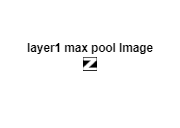

title('layer1 max pool Image');

filter_values_2 = squeeze(h5read('my_checkpoint.weights.h5', '/layers/conv2d_1/vars/0'))';

bias_2=squeeze(h5read('my_checkpoint.weights.h5', '/layers/conv2d_1/vars/1'));
conv_result_2 = conv2_same_size_no_flip(pooled_output_1, filter_values_2)+bias_2;
conv_clipped_2 = max(conv_result_2, 0);
% Display the result
imshow(conv_clipped_2, []);
conv_clipped_2

conv_clipped_2 = 14×14 single matrix
         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.1197    1.8683    0.5099    0.5162    0.5296    0.5227         0         0         0         0         0         0         0         0
    2.6455    5.6808    5.2311    5.2281    5.0272    2.8924         0         0         0         0         0         0    1.7817    1.1908
         0    1.2365    2.0959    1.8449         0         0         0         0         0         0         0    0.3669    2.0819    2.8978
    0.0904         0         0         0         0         0         0         0         0         0    0.5844    1.5256    1.8643    1.1815
    0.0897         0         0         0         0         0         0         0         0    0.8709    1.7097    1.9

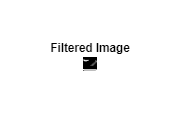

title('Filtered Image');

%max pool layer2
size=14;
% Define pooling window size
pool_size = 2;
% Initialize output size
pooled_output2 = zeros(floor(size/pool_size), floor(size/pool_size));

% Perform 2x2 max pooling
for i = 1:pool_size:size-pool_size+1
    for j = 1:pool_size:size-pool_size+1
        block = conv_clipped_2(i:i+1, j:j+1);
        pooled_output2((i+1)/2, (j+1)/2) = max(block(:));
    end
end

% Display the input and pooled result
imshow(pooled_output2, []);
pooled_output2

pooled_output2 =          0         0         0         0         0         0         0
    5.6808    5.2311    5.0272         0         0         0    1.7817
    1.2365    2.0959         0         0         0    1.5256    2.8978
    0.0897         0         0         0    2.1153    2.2201    0.8562
         0         0         0    1.0619    2.0089    1.0113    0.0858
         0         0         0         0         0         0         0
    6.0642    4.7025    4.7046    4.7123    4.7095    4.7020    5.9987


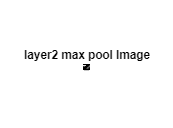

title('layer2 max pool Image');

filter_values_3 = squeeze(h5read('my_checkpoint.weights.h5', '/layers/conv2d_2/vars/0'))';

bias_3=squeeze(h5read('my_checkpoint.weights.h5', '/layers/conv2d_2/vars/1'));
conv_result3 = conv2_same_size_no_flip(pooled_output2, filter_values_3)+bias_3;
conv_clipped3 = max(conv_result3, 0);
% Display the result
imshow(conv_clipped3, []);
conv_clipped3

conv_clipped3 = 7×7 single matrix
   12.8274   11.9508    5.0558         0         0    2.3592    1.8288
    7.3725    5.7000    1.4084    0.3743    2.0181    6.1409    3.3245
    1.9296    1.0147    0.5925    2.6294    5.7450    4.8746    1.7732
    0.1738    0.2112    1.3280    4.6119    4.7394    2.2874    0.7115
         0         0    0.4140    1.0362    1.1818    0.6001    0.1123
   12.5199   10.9650   11.0183   11.1613   11.2224   12.7782    6.0491
    3.1714    3.3503    3.2488    3.2495    3.2465    3.7670    1.6261


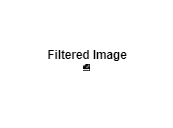

title('Filtered Image');

%max pool layer3
size=7;
% Define pooling window size
pool_size = 2;
% Initialize output size
pooled_output3 = zeros(floor(size/pool_size), floor(size/pool_size));

% Perform 2x2 max pooling
for i = 1:pool_size:size-pool_size+1
    for j = 1:pool_size:size-pool_size+1
        block = conv_clipped3(i:i+1, j:j+1);
        pooled_output3((i+1)/2, (j+1)/2) = max(block(:));
    end
end

% Display the input and pooled result
imshow(pooled_output3, []);
pooled_output3

pooled_output3 =    12.8274    5.0558    6.1409
    1.9296    4.6119    5.7450
   12.5199   11.1613   12.7782


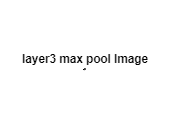

title('layer3 max pool Image');

% Step 1: Read the file into a vector

flattened_9x1 = reshape(pooled_output3', 1, [])

flattened_9x1 =    12.8274    5.0558    6.1409    1.9296    4.6119    5.7450   12.5199   11.1613   12.7782


%weights = load('dense_weights.mem');  % assumes decimal values line-by-line
% Step 2: Check if the number of values is correct
% if numel(weights) ~= 9*18
%     error('Expected 162 values to form a 9x18 matrix.');
% end
% Step 3: Reshape the vector into a 9x18 matrix
% dense_matrix = reshape(weights, [18,9])';  % Transpose for 9 rows, 18 cols
% 
% Step 4: Display or use the matrix
% disp('Dense Weight Matrix (9x18):');
% disp(dense_matrix);
%h5disp('my_checkpoint.weights.h5');
dense_weights_1 = h5read('my_checkpoint.weights.h5', '/layers/dense/vars/0')'  % size: 18x9

dense_weights_1 = 9×18 single matrix
   -0.5276   -0.3529    0.5281    0.3625    0.4341   -0.1641    0.2570    0.1827    0.0622    0.2321    0.7369   -0.1948   -0.5215    0.3276    0.1546   -0.3856    0.0202    0.3152
    0.2393    0.3013    0.5012   -0.2097   -0.2067   -0.1396    0.2040    0.3330   -0.1448    0.0990   -0.4959    0.2796    0.4890   -0.1009    0.5373   -0.3024    0.0816    0.2375
    0.1105    0.3114   -0.4181    0.4478   -0.2114   -0.1353   -0.0728    0.4827   -0.0160    0.3338    0.7020    0.5293    0.4358   -0.4852   -0.3136   -0.1552    0.0257   -0.5394
    0.4225    0.0013   -0.2871    0.0357    0.2818    0.3919   -0.1165   -0.0323   -0.0581   -0.2004    0.3126    0.4513   -0.0850    0.3137   -0.3049   -0.3341   -0.3128    0.3090
    0.6487    0.1502    0.3261   -0.2098   -0.0494    0.8421    0.4180   -0.2965    0.3344   -0.1059   -0.1241   -0.2956    0.1093   -0.2060    0.0018    0.1689    0.4368   -0.0558
    0.4072    0.3356   -0.0826   -0.0649    0.1397    0.21



% Step 3: Reshape the vector into a 9x18 matrix
bias_matrix = h5read('my_checkpoint.weights.h5', '/layers/dense/vars/1')'  % Transpose for 9 rows, 18 cols

bias_matrix = 1×18 single row vector
   -0.0020   -0.0612   -0.0287    0.0281    0.0655    0.0425    0.0286   -0.0647   -0.0717   -0.0636    0.0158   -0.0163   -0.2130    0.3768    0.2124    0.2736    0.1364    0.1281



% Step 4: Display or use the matrix

disp(bias_matrix);

   -0.0020   -0.0612   -0.0287    0.0281    0.0655    0.0425    0.0286   -0.0647   -0.0717   -0.0636    0.0158   -0.0163   -0.2130    0.3768    0.2124    0.2736    0.1364    0.1281




final_1 = max((flattened_9x1*dense_weights_1)+bias_matrix,0)

final_1 = 1×18 single row vector
    0.5385    4.2135    6.9314   11.4684   11.9078    3.8640    3.9550   10.7683    7.4083    8.3658   12.3413    1.2034    9.2906    9.2810    1.7311    4.1800    3.8097    5.4141



dense_weights_2 = h5read('my_checkpoint.weights.h5', '/layers/dense_1/vars/0')'  % 36x18

dense_weights_2 = 18×36 single matrix
   -0.0256   -0.8133   -0.3896    0.1081   -0.1864    0.2177   -0.1499   -0.1416    0.1912   -0.1013   -0.0871   -0.1866   -0.2614   -0.5235   -0.1962    0.1729   -0.1998    0.0524   -1.2874   -1.1729   -0.1324   -2.1474   -0.0281   -0.4915    0.0258    0.1895   -0.3856   -0.0624    0.2942   -0.5490   -0.8398   -0.5192   -0.7432   -0.9169   -0.3194   -0.8434
   -0.1937   -0.1311   -0.0464   -0.1881   -0.2440   -0.1130   -0.2992   -0.6609   -0.2506    0.1909    0.1635    0.1072   -0.0259    0.1118    0.2323   -0.2530   -0.0142   -0.2907    0.0536   -1.1905    0.0745   -0.3760   -0.2106   -0.1374   -0.4007   -0.4248    0.3484    0.1279    0.0191   -0.0162   -1.2675   -0.3907   -0.0767    0.3474    0.0110   -0.2018
   -0.2939    0.1302   -0.0419    0.3306   -1.0264   -0.1680   -0.5531    0.2574    0.1378   -0.5017   -0.3850    0.1542   -0.5058    0.2147   -0.2057   -0.3234   -0.2304   -0.3357   -0.4415   -0.2852   -0.9668   -0.1311   -0.4973   -0.2493



% Step 3: Reshape the vector into a 9x18 matrix
bias_matrix_2 = h5read('my_checkpoint.weights.h5', '/layers/dense_1/vars/1')';  % Transpose for 9 rows, 18 cols

% Step 4: Display or use the matrix

disp(bias_matrix_2);

    0.0254    0.0212   -0.1474   -0.1048    0.0132    0.0421   -0.0519    0.0149   -0.1139    0.0215   -0.0152    0.0055   -0.1550    0.1663   -0.0748   -0.0357   -0.1274   -0.0186    0.0354    0.0678   -0.2381    0.0230    0.0174   -0.1222   -0.0564    0.0573   -0.1317   -0.1307   -0.3162   -0.0394    0.0441    0.1743    0.3174   -0.1119   -0.0792    0.0032




final_2 = (final_1*dense_weights_2)+bias_matrix_2

final_2 = 1×36 single row vector
  -23.1496  -17.0885   -8.5802  -13.0359  -23.2461  -19.7256  -25.8515  -22.4017  -20.4260  -29.6130  -23.5958  -17.8051  -20.2466  -15.6274  -14.3981  -25.7720  -17.5860  -26.3071  -13.4535  -13.8974  -24.6888  -20.2916  -22.3252  -14.7259  -21.7471  -26.2826  -16.5133  -13.8616  -24.5656  -15.0502  -21.4540  -22.1824  -15.0000   -6.4586  -13.4492   -5.0614


softmax_output = exp(final_2) / sum(exp(final_2))

softmax_output = 1×36 single row vector
    0.0000    0.0000    0.0232    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.1935    0.0002    0.7823


labels = ['0':'9', 'A':'Z'];  % Total 36 classes

% Get indices of Top 3 values (sorted descending)
[sorted_probs, sorted_indices] = sort(softmax_output, 'descend');
top3_indices = sorted_indices(1:3);
top3_probs = sorted_probs(1:3);
top3_labels = labels(top3_indices);

% Display Top-3 results
fprintf('Top 3 Predicted Labels:\n');

Top 3 Predicted Labels:


for i = 1:3
    fprintf('%d. Label: %s | Probability: %.4f\n', i, top3_labels(i), top3_probs(i));
end

1. Label: Z | Probability: 0.7823
2. Label: X | Probability: 0.1935
3. Label: 2 | Probability: 0.0232


function output_image = conv2_same_size_no_flip(input_image, kernel)
    % Check if the kernel size is 3x3
    [kernel_rows, kernel_cols] = size(kernel);
    if kernel_rows ~= 3 || kernel_cols ~= 3
        error('The kernel must be 3x3.');
    end
    
    % Get the size of the input image
    [image_rows, image_cols] = size(input_image);
    
    % Pad the input image with zeros on all sides
    padded_image = padarray(input_image, [1, 1], 'both');
    
    % Initialize the output image with zeros
    output_image = zeros(image_rows, image_cols);
    
    % Perform the convolution without flipping the kernel
    for i = 1:image_rows
        for j = 1:image_cols
            % Extract the 3x3 region around the current pixel
            region = padded_image(i:i+2, j:j+2);
            
            % Apply the convolution operation (element-wise multiplication and sum)
            output_image(i, j) = sum(sum(region .* kernel));
        end
    end
    
    % Display the output image (optional)
    % imshow(output_image, []);
end

